%input
f0 = 1000; % frek to notch
Qfactor = 0.9;

slope = 0.9900


fsample = 44000; % sampling frequency Nyquist = 22000 Hz
N = 44000;

fcut_Norm = 0.0455


% Angle to the freq
w0 = 2*pi*(f0/fsample) 

w0 = 0.1428


% Alpha with Q factor
alpha1 = (sin(w0)) / (2*Qfactor) % S -> alpha2 = (sin(w0)/2) * sqrt((A+(1/A))*((1/slope)-1)+2)

alpha1 = 0.0791


% Notch filter Coeff b
b0 = 1; 
b1 = -2*cos(w0); 
b2 = 1;
b = [b0, b1, b2]

b =     1.0000   -1.9796    1.0000



% Notch filter Coeff a
a0 = 1+alpha1; 
a1 = -2*cos(w0); 
a2 = 1-alpha1;
a = [a0, a1, a2]

a =     1.0791   -1.9796    0.9209


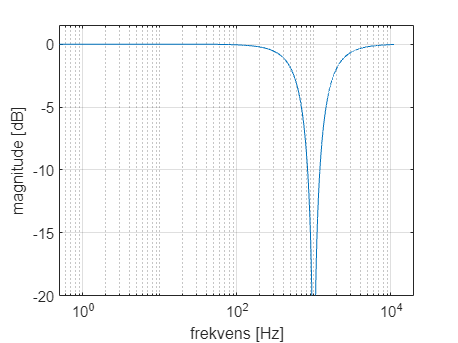


h = freqz(b,a,fsample); 

%Frekvens akse i log 
f_oploesning = fsample/N; % frekvens opløsning
f_akse = (0:f_oploesning:fsample - f_oploesning); 
X_dB_norm = 20*log10(abs(h));

semilogx(f_akse(1:end/2)/2, X_dB_norm(1:end/2))
%plot(f_akse(1:end/2)/2, abs(h(1:end/2)))
grid on 
xlim([0, 20000]) 
ylim([-20, 1.5]) 
xlabel("frekvens [Hz]") 
ylabel("magnitude [dB]")